# **IO750 - EtherCAT Drive Control**

The IO750 is an EtherCAT subordinate device module to connect real-time target machines to industrial devices such as programmable logic controllers. The IO750 handles the complete data exchange between the connected EtherCAT main device and the real-time application. The data exchange is processed via a dual-port memory. The module acts as one subordinate device exclusively. The two Ethernet connectors enable easy network integration.

This example demonstrates communications between the IO750 EtherCAT subordinate device I/O module and the native EtherCAT main device implementation that is supported with the target machine's Ethernet interfaces. The subordinate device simulates a motor controller, providing process data objects (PDOs) and service data objects (SDOs) that the main device can read and write. Typical PDOs are target velocity and actual position. Typical SDOs are serial number and the homing command.

The configuration of the IO750 EtherCAT subordinate device can be completely done in Simulink with the help of the [IO750 Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io750_setup_v2) block. The block defines the device's identity, and also the local process and service data objects. PDO and SDO blocks are used to read and write these objects.

The EtherCAT main device configuration requires an EtherCAT Network Information (ENI) file. The file is created with TwinCAT, a software tool from Beckhoff. The file describes all connected subordinate devices and their process data objects. The generation of the file requires the EtherCAT SubDevice Information (ESI) files of the connected devices to be imported into TwinCAT. For the IO750, the file can be exported from the [IO750 Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io750_setup_v2) block.

The EtherCAT main device is configured by the [EtherCAT Init](https://mathworks.com/help/slrealtime/io_ref/ethercatinit.html) block using the ENI file. PDO and SDO blocks are used to read and write the subordinate device's PDOs and SDOs.

## Setup

### Prerequisites

You will require the following to run this example:

- Speedgoat real-time target machine with one IO750 I/O module installed

- One unused Ethernet interface, either onboard or with an IO71x/IO791 Ethernet I/O module

- CAT5 Ethernet cable or newer

The MainDevice configuration requires an ENI file. This file comes with the example model and does not have to be created in TwinCAT. However, the TwinCAT project is included in the example and can be used to recreate the ENI file. TwinCAT is free of charge. Find the download link in the Additional References section below.

### Test Setup

EtherCAT is an Ethernet-based protocol. Use a CAT5 cable or newer to connect the main device and the subordinate device. For the main device, choose an unused RJ45 Ethernet connector, an onboard interface or an IO71x/IO791 module. Plug the other end of the cable into an RJ45 connector of the IO750 EtherCAT subordinate device module according to the following instructions:

- For the Performance real-time target machine, use the upper port

- For the Mobile machine, use the right port

- For the Baseline and Unit machines, use the left port

To activate EtherCAT support for the respective interface, enter the following in the MATLAB command window to open the Ethernet Configuration Tool:

Select **EtherCAT** in the **Configuration** column for the chosen interface, as shown below for the ETH2 interface:

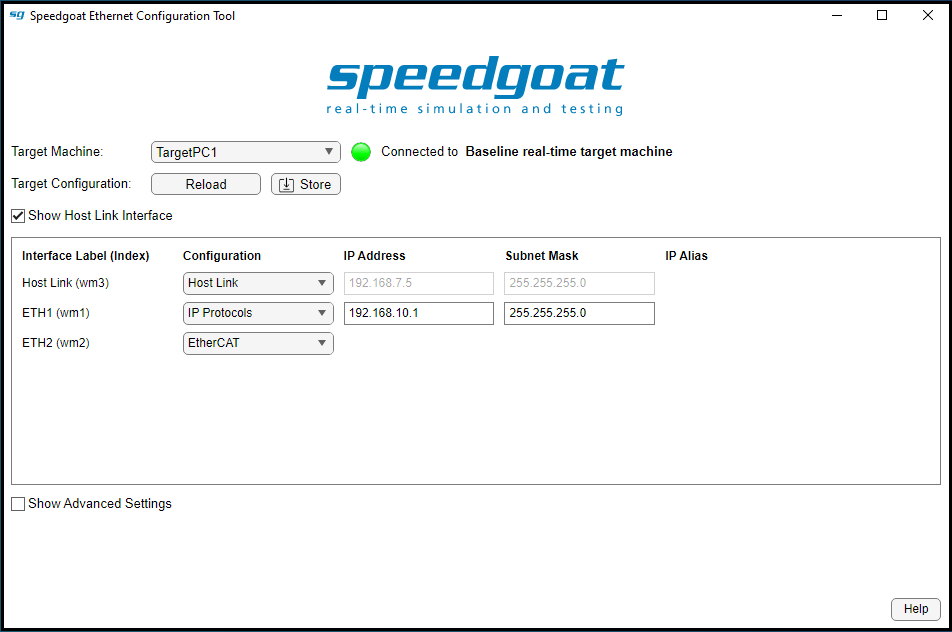

## Initialize and Open the Simulink Model

 
% Sample time
Ts = 0.001;

% Open Simulink model
modelName = 'sgMdl_IO750_EtherCATDriveControl';
open_system(modelName);

### Model Description

The model simulates a plant controller and a motor controller, communicating via EtherCAT. The plant controller acts as an EtherCAT main device in the network, the motor controller as an EtherCAT subordinate device. The main device sends the target velocity to the subordinate device and monitors the actual velocity and position values received. This part of the communication is done via PDOs. After a period of time, the main device prompts the subordinate device to change the controlled system behavior and reset the position. This part is done via SDOs.

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model.

 
% Build the Simulink model
slbuild(modelName);         % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;
tg.connect;

% Download and install the real-time application on the target machine
tg.load(modelName);

% Prepare the Simulink Data Inspector to plot signals
Simulink.sdi.clearAllSubPlots;
Simulink.sdi.setSubPlotLayout(3,1);
Simulink.sdi.view;

% Start the real-time application
tg.start;

% Select the signals for plotting, set the axis limits and line colors
sdiRunIDs = Simulink.sdi.getAllRunIDs;
sdiLatestRun = Simulink.sdi.Run.getLatest;
s = sdiLatestRun.getSignalsByName('TargetSpeed');
plotOnSubPlot(s,1,1,true);
s.LineColor = [0.6350 0.0780 0.1840];
s = sdiLatestRun.getSignalsByName('ActualSpeed');
plotOnSubPlot(s,1,1,true);
s.LineColor = [0.8500 0.3250 0.0980];
s = sdiLatestRun.getSignalsByName('ActualPosition');
plotOnSubPlot(s,2,1,true);
s.LineColor = [0 0.4470 0.7410];
s = sdiLatestRun.getSignalsByName('StatusWord');
plotOnSubPlot(s,3,1,true);
s.LineColor = [0.4940 0.1840 0.5560];
s = sdiLatestRun.getSignalsByName('Mode');
plotOnSubPlot(s,3,1,true);
s.LineColor = [0.4660 0.6740 0.1880];
s = sdiLatestRun.getSignalsByName('Homing');
plotOnSubPlot(s,3,1,true);
s.LineColor = [0.9290 0.6940 0.1250];
Simulink.sdi.setSubplotLimits(1,1,'AllRange',[0,40,-20,80]);
Simulink.sdi.setSubplotLimits(2,1,'AllRange',[0,40,-50,850]);
Simulink.sdi.setSubplotLimits(3,1,'AllRange',[0,40,-1,16]);

### Check the Results

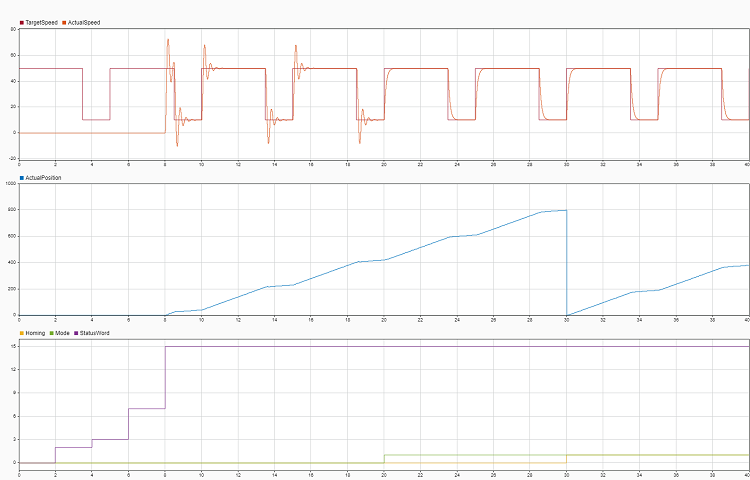

## Additional References

- [IO750 documentation and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_io750)

- [Native EtherCAT MainDevice documentation and examples](https://www.mathworks.com/help/slrealtime/ethercat.html)

- [TwinCAT download source](https://www.beckhoff.com/de-de/produkte/automation/twincat/texxxx-twincat-3-engineering/te1000.html)